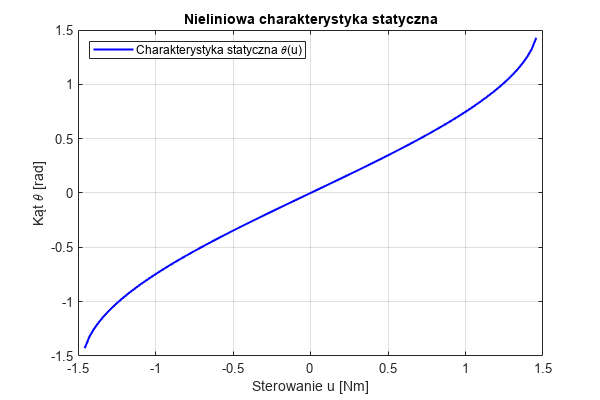

if ~exist('MGL', 'var')
    error('Uruchom najpierw skrypt parametry.m!');
end

u = linspace(-u_range_limit, u_range_limit, 100);

% === CHARAKTERYSTYKA NIELINIOWA ===
% Wzór: theta = asin(u / (m*g*l))
f_nieliniowa = @(u) asin(u ./ MGL);

y = f_nieliniowa(u);

figure('Position', [100, 100, 600, 400]);
plot(u, y, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Sterowanie u [Nm]');
ylabel('Kąt \theta [rad]');
legend('Charakterystyka statyczna \theta(u)', 'Location', 'northwest'); 
title('Nieliniowa charakterystyka statyczna');
print('charStat.png', '-dpng', '-r400');

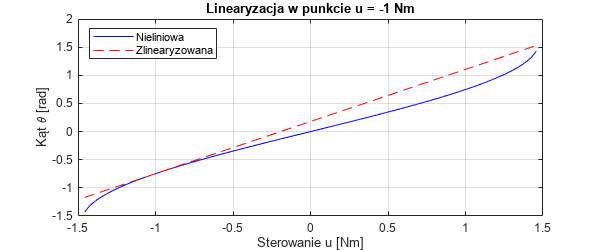



% === LINEARYZACJA ===
% Pochodna funkcji asin(u/A) to: 1 / sqrt(A^2 - u^2)
% Wzór Taylora: y_lin = y0 + pochodna * (u - u0)

slope = @(u0) 1 ./ sqrt(MGL^2 - u0.^2);

% --- Punkt 1: ulin1 ---
y0_1 = f_nieliniowa(ulin1);
k1 = slope(ulin1);
flin1 = @(u) y0_1 + k1 * (u - ulin1);

ylin1 = flin1(u);

figure('Position', [100, 100, 600, 250]);
plot(u, y, 'b', u, ylin1, 'r--');
grid on;
xlabel('Sterowanie u [Nm]');
ylabel('Kąt \theta [rad]');
legend('Nieliniowa', 'Zlinearyzowana', 'Location', 'northwest'); 
title(['Linearyzacja w punkcie u = ' num2str(ulin1) ' Nm']);
print('charStatLin1.png', '-dpng', '-r400');

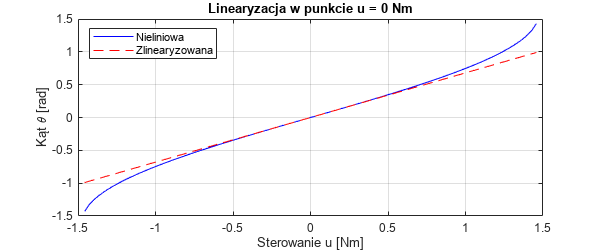



% --- Punkt 2: ulin2 (PION, u=0) ---
y0_2 = f_nieliniowa(ulin2);
k2 = slope(ulin2); % W tym punkcie wzmocnienie jest najmniejsze
flin2 = @(u) y0_2 + k2 * (u - ulin2);

ylin2 = flin2(u);

figure('Position', [100, 100, 600, 250]);
plot(u, y, 'b', u, ylin2, 'r--');
grid on;
xlabel('Sterowanie u [Nm]');
ylabel('Kąt \theta [rad]');
legend('Nieliniowa', 'Zlinearyzowana', 'Location', 'northwest'); 
title(['Linearyzacja w punkcie u = ' num2str(ulin2) ' Nm']);
print('charStatLin2.png', '-dpng', '-r400');

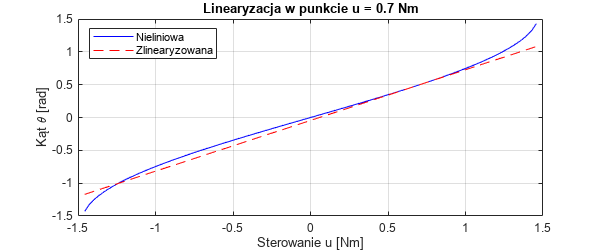



% --- Punkt 3: ulin3 ---
y0_3 = f_nieliniowa(ulin3);
k3 = slope(ulin3);
flin3 = @(u) y0_3 + k3 * (u - ulin3);

ylin3 = flin3(u);

figure('Position', [100, 100, 600, 250]);
plot(u, y, 'b', u, ylin3, 'r--');
grid on;
xlabel('Sterowanie u [Nm]');
ylabel('Kąt \theta [rad]');
legend('Nieliniowa', 'Zlinearyzowana', 'Location', 'northwest'); 
title(['Linearyzacja w punkcie u = ' num2str(ulin3) ' Nm']);
print('charStatLin3.png', '-dpng', '-r400');


% Wyświetlenie wzmocnień w konsoli (dla sprawdzenia)
disp('--- Wzmocnienia statyczne (K_stat) ---');

--- Wzmocnienia statyczne (K_stat) ---


disp(['Dla u = ' num2str(ulin1) ': ' num2str(k1)]);

Dla u = -1: 0.92636


disp(['Dla u = ' num2str(ulin2) ': ' num2str(k2)]);

Dla u = 0: 0.67958


disp(['Dla u = ' num2str(ulin3) ': ' num2str(k3)]);

Dla u = 0.7: 0.7726
